# 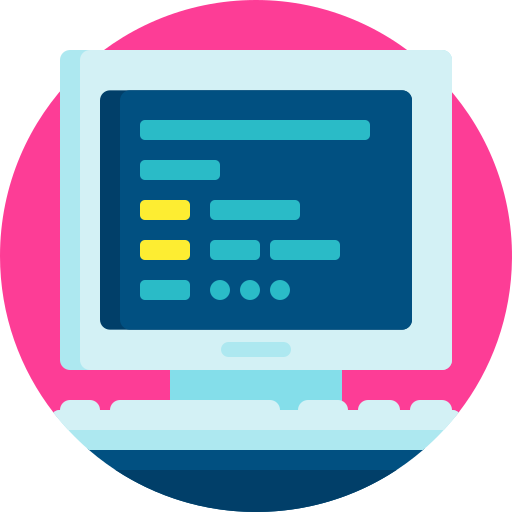

# Virtual Lab 6: Closed-loop stability

**This Virtual Lab covers content in Chapter 9 of the course notes**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## Introduction

As shown for open-loop systems in the previous chapters, stability is a key requirement of a system in order to have the potential to meet a set of performance specifications. Unstable systems result in diverging output responses that render the concepts of settling time, overshoot, etc irrelevant, which means that we have no chance in controlling the output. 

We will now extend the concept of stability to that of closed-loop systems. It will be shown that the idea of closed-loop stability is analogous to that of open-loop systems and is predicated on the pole location(s) in the s-plane. We will then explore frequency-domain methods that can be used to assess system closed-loop stability given knowledge of the open-loop system's frequency response. This methodology will form the basis of future frequency-domain analysis and design techniques in this course.

## General stability

### Closed-loop poles and zeros

In a previous chapter the concept of stability was introduced, which is based on the location of the poles in the s-plane. Specifically, if *all* poles of a system lie in the open left half-plane of the s-plane, or OLHP (requiring the real components of all poles to be strictly less than zero), the system is deemed strictly (or BIBO) stable. This concept can be extended to closed-loop systems without loss of generality. Consider the two equivalent closed-loop systems below

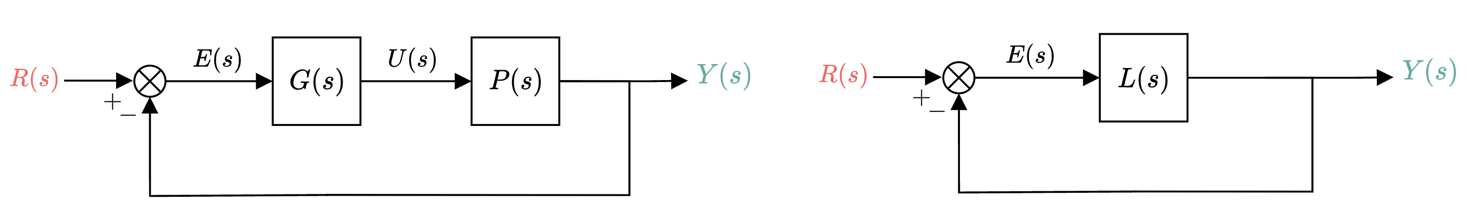

where $L(s)=P(s)G(s)$ is the open-loop transfer function. If $R(s)$ is our setpoint (or desired output signal) and we would like output $Y(s)$ to approach $R(s)$ in some sense, then we need to first ensure that the transfer behaviour from $R(s)$ to $Y(s)$ is stable. We can define $L(s)$ as a ratio of polynomials

$L(s)=\frac{N(s)}{D(s)}$,

where the roots of $N(s)=0$ are equal to the open-loop zeros and the roots of $D(s)=0$ correspond to the open-loop poles. The transfer behaviour from $R(s)$ to $Y(s)$ is easily determined as

$\frac{Y(s)}{R(s)}=T(s)=\frac{L(s)}{1+L(s)}$,

where $T(s)$ is the complementary sensitivity function as introduced in **Chapter 8**. This can be reposed as a ratio of polynomials from $L(s)$, namely

$\frac{L(s)}{1+L(s)}=\frac{N(s)/D(s)}{1+N(s)/D(s)}=\frac{N(s)}{N(s)+D(s)}$.

The above result implies that the zeros of $L(s)$, arising from solving $N(s)=0$, will be equivalent to the zeros of $T(s)$. The closed-loop poles are determined by finding the roots of $N(s)+D(s)=0$. Therefore *both *the open-loop poles *and* open-loop zeros affect the closed-loop poles (an important insight that we will explore in a later chapter). We can also determine the closed-loop poles by finding the roots of 

$1+L(s)=1+N(s)/D(s)=0$,

which after multiplying both sides by $N(s)$ is equivalent to


$$N(s)+D(s)=0$$


The closed-loop system is then defined as stable if the closed-loop poles lie in the open left half-plane of the s-plane. Assuming we knew $L(s)$, we could then find the roots of $1+L(s)$ in order to assess whether the closed-loop system is stable. 

####  Question 1: Determine the closed-loop poles of $L(s)=\frac{c}{s^2+bs}$, $c>0$ when placed in a unit-feedback configuration.

####  Question 2: Using your answer from Question 1, under what condition will $T(s)=\frac{L(s)}{1+L(s)}$ be stable?

While there is technically nothing wrong with this exercise, the process of continually checking closed-loop stability based on pole location (by finding the roots of $1+L(s)=0$) is time-consuming and inefficient. However, it turns out that there is actually a very convenient approach that we can use to assess closed-loop stability based on the frequency response, without having to analytically determine the closed-loop pole locations every time. This concept is presented in the following sections.

### The critical point

Consider the closed-loop system below,

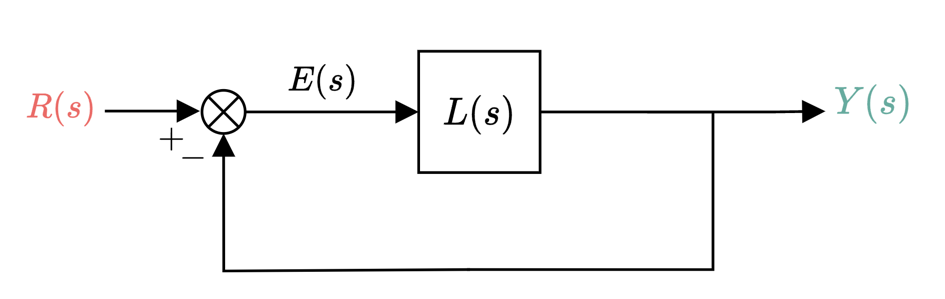

where the closed-loop relationship between $R(s)$ and $Y(s)$, namely the complementary-sensitivity function, is

$T(s)=\frac{L(s)}{1+L(s)}$.

The frequency response of $T(s)$ follows as

$T(j\omega)=\lim_{s\rightarrow j\omega}T(s)=\frac{L(j\omega)}{1+L(j\omega)}$.

Additionally, the frequency response magnitude (in arithmetic units) is 

$|T(j\omega)|=\frac{|L(j\omega)|}{|1+L(j\omega)|}$.

Given some frequency $\omega_{0}$, when $L(j\omega_0)=-1$, $|T(j\omega_0)|$ tends to infinity (the denominator of the above equation goes to zero, resulting in $|T(j\omega_0)|\rightarrow \infty$). In other words, under this condition, an input sinusoid with frequency $\omega_0$ will result in an infinitely large, unbounded output signal. This means that our closed-loop system will become marginally stable when $L(j\omega_0)=-1$, which based on our definition of bounded-input-bounded-output stability means that the closed-loop system is not strictly stable. We therefore need to avoid our loop frequency response from ever being $L(j\omega)=-1$. 

The "-1" quantity is known as the **critical point** and is an important means of assessing stability. The above interpretation means that if $L(j\omega)$, represented on a Nyquist plot, intersects the critical point (equal to $-1=e^{\pm j\pi}$) then our closed-loop system is not strictly stable. We can visualise the critical point on a Nyquist plot, as shown below, which is located at $(-1,0)$.

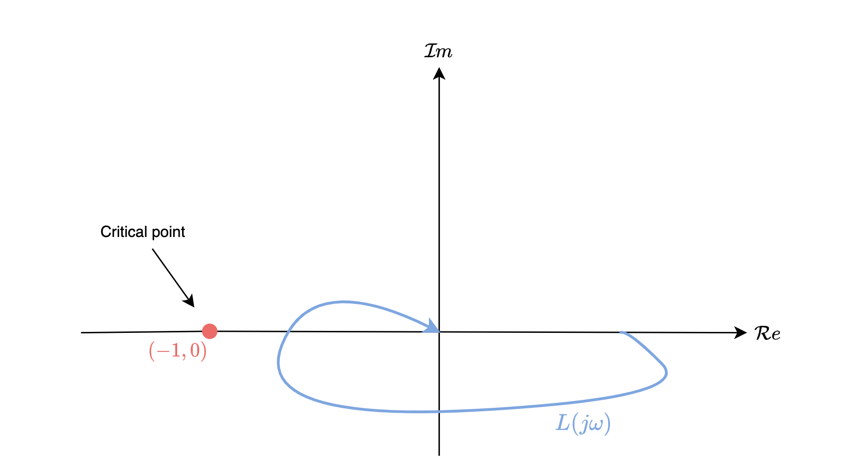

####  Question 3: Determine the frequency at which $L(s)=\frac{1}{s}e^{-\frac{\pi}{2}s}$ intersects the critical point.

####  Question 4: Using your answer in Question 3, determine whether the closed-loop system $T(s)=\frac{L(s)}{1+L(s)}$ will be stable or unstable.

%Code block (if required)


## Closed-loop stability from open-loop frequency response

In this course we will only consider open-loop systems that are marginally or strictly stable when assessing closed-loop stability. That is, open-loop systems with poles in the closed left half-plane (CLHP). Under this condition, we can assess the closed-loop stability of our system using the frequency response, based on the so-called *Nyquist stability criterion* (we will not cover this in **MEC3079S**, but will rather just use one of the results without proof). 

### Phase crossover frequency and gain crossover frequency

Before making use of the Nyquist stability criterion, we need to define two key frequencies, namely phase crossover frequency and gain crossover frequency.

The **phase crossover frequency**, $\omega_{pc}$, is defined as the frequency at which $\angle L(j\omega_{pc})=-180^\circ$. In other words, the frequency where the phase of the loop transfer function is equal to $-180^\circ$. The name is fairly literal in that $\omega_{pc}$ indicates the frequency at which the phase *crosses over* the $-180^\circ$ phase line. Note that not all systems will possess a phase crossover frequency.

The **gain crossover frequency**, $\omega_{gc}$, is defined as the frequency at which $| L(j\omega_{gc})|=1$ (or $| L(j\omega_{gc})|_{dB}=0$ dB in logarithmic units). In other words, the frequency where the loop transfer function has unit magnitude. The name refers to the frequency, $\omega_{gc}$, at which the gain *crosses over* the $1$ (or $0$ dB) gain line. Note that not all systems will possess a gain crossover frequency.

####  Question 5: Algebraically determine the gain crossover frequency of $L(s)=\frac{10}{s(s+1)}$. Provide your answer to two decimal places.

%Code block (if required)


####  Question 6: Determine the phase crossover frequency of $L(s)=\frac{10}{s(s+1)}$.

### Determining stability

According to the Nyquist stability criterion, given that $\omega_{pc}$ is the frequency that corresponds with $\angle L(j\omega_{pc})=\pm180^\circ$ (assuming such a frequency exists), if $|L(j\omega_{pc})|<1$, the system will be closed-loop stable. In other words, the gain of the open-loop transfer function must be less than unity when the phase angle is equal to $-180^\circ$. If the above-mentioned condition is not met, the closed-loop system will then be unstable. This includes if $L(j\omega_{pc})=-1$. Note that if a $\omega_{pc}$ does not exist that satisfies $\angle L(j\omega_{pc})=-180^\circ$, then the closed-loop system is still stable.

We can perform calculations to check for the above condition, but an easier approach is to visualise the frequency response data on an appropriate diagram (such as a Bode plot, Nyquist plot, or log-polar plot) and then visually assess whether the above condition is met. 

### Stability from Nyquist diagrams

Recall that in a Nyquist diagram, the real and imaginary components of the frequency response are plotted for each frequency, running from $\omega=0$, to $\omega\rightarrow\infty$ using the rectangular form of

    $L(j\omega)=a(\omega)+jb(\omega)$.

On a Nyquist plot, the phase crossover frequency occurs when the phase angle of $L(j\omega)$ is equal to $-180^\circ$. This corresponds to when the frequency response locus intersects the *negative-real axis*. Because the critical point is located a distance of 1 from the origin, if the intersection of the negative-real axis occurs to the *right* of the critical point, as shown for $L_1(j\omega)$, then $|L_1(j\omega_{{pc}_1})|<1$ and the corresponding closed-loop system $T_1(j\omega)$ will be stable. If the intersection of the negative-real axis occurs to the *left* of the critical point, as shown for $L_2(j\omega)$, then $|L_2(j\omega_{{pc}_2})|>1$ and based on Nyquist stability criterion, the corresponding $T_2(j\omega)$ will be unstable. In short, when represented on a Nyquist plot, we require that our frequency response locus does not encircle the critical point in order to ensure closed-loop stability.

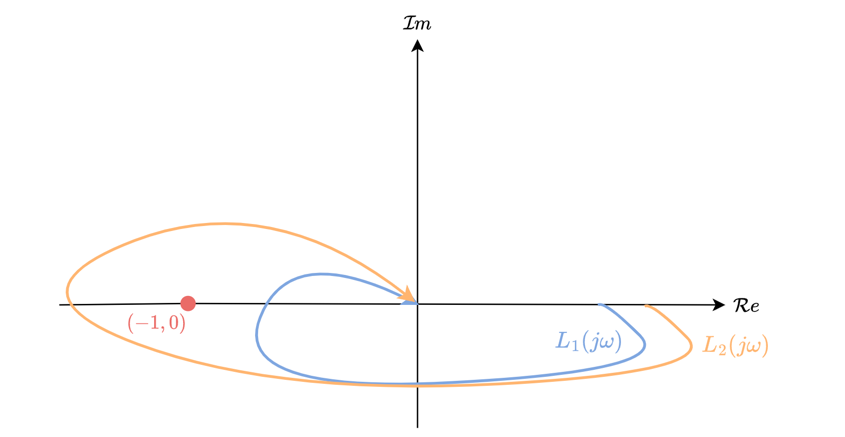

### Stability from Bode diagrams

Recall that the Bode diagram plots the logarithmic magnitude, $20\log_{10}|L(j\omega)|$, and phase response, $\angle L(j\omega)$, in degrees, separately against logarithmic frequency, $\log_{10}\omega$.

For Bode diagrams, we begin by identifying the frequency, $\omega_{pc}$, at which the phase angle of our open-loop system is equal to $-180^\circ$, namely when $\angle L(j\omega_{pc})=-180^\circ$. Once we identify the frequency, we then check the corresponding magnitude response at $\omega_{pc}$ to see if the gain is less than unity: $|L(j\omega_{pc})|<1$. In the case of plotting magnitudes in decibels, this corresponds to checking whether $|L(j\omega_{pc})|_{dB}<0$ dB.

As shown in the figure below, $T_1(s)$ will be stable based on $|L_1(j\omega_{pc})|_{dB}=-6<0$ dB, whereas $T_2(s)$ will be unstable based on $|L_2(j\omega_{pc})|_{dB}=2>0$ dB.

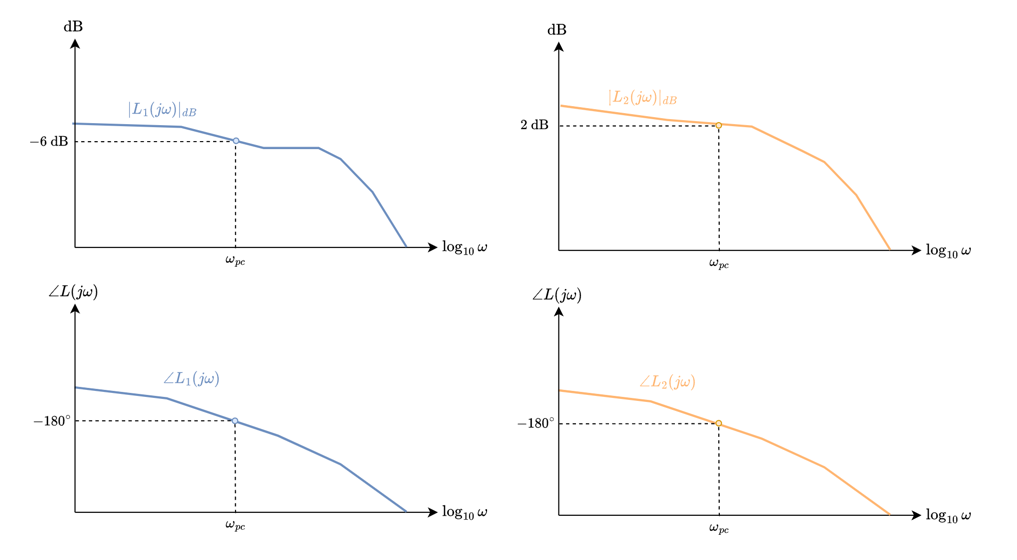

Example code for generating the Bode diagram of $L(s)=\frac{1}{1+s}$ is given below.

%Example
clear 
s = tf('s');
L = 1/(1+s);

figure, hold on
bode(L)
grid on

####   **Task: In the code block below, generate the Bode diagram of **$L(s)=\frac{10(1+s)}{s^2(1+s/10)^2}$, and assess the closed-loop stability using the Nyquist stability criterion.

%Code block for task


####  Question 7: Using the generated Bode diagram, determine the approximate phase crossover frequency of $L(s)$.

####  Question 8: Based on the Nyquist stability criterion, determine whether $T(s)=\frac{L(s)}{1+L(s)}$ be stable or unstable?

%Code block (if required)


### Stability from log-polar plots

Log-polar plots can also be used to assess closed-loop stability based on the open-loop frequency response. Because the phase angle of $L(j\omega)$ is plotted against the (logarithmic) magnitude of $L(j\omega)$, all we need to do is check that the frequency response locus passes *below* the critical point of $-1$, which is represented on the log-polar plot by $(0~ \text{dB}, -180^\circ)$.

As shown in the figure below, $T_1(s)$ will be stable based on the $L_1(j\omega)$ locus passing *below* the critical point (implying $|L_1(j\omega_{pc})|_{dB}<0$ dB), whereas $T_2(s)$ will be unstable based on the $L_2(j\omega)$ locus passing *above* the critical point (implying $|L_2(j\omega_{pc})|_{dB}>0$ dB).

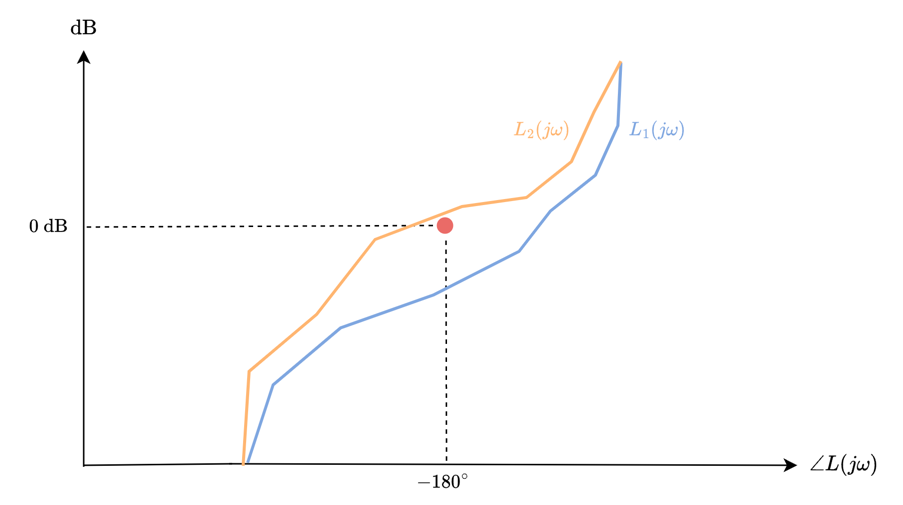

Example code for generating the log-polar plot of $L(s)=\frac{1}{1+s}$ is given below.

%Example
s = tf('s');
L = 1/(1+s);

figure, hold on
nichols(L)

####   **Task: In the code block below, generate the log-polar plot of **$L(s)=\frac{20(1+s)}{s^2(1+s/10)^2}$, and assess the closed-loop stability using the Nyquist stability criterion.

%Code block for task


####  Question 9: Based on the Nyquist stability criterion, determine whether $T(s)=\frac{L(s)}{1+L(s)}$ be stable or unstable?

%Code block (if required)


## Margins of stability

We have now identified a frequency response methodology that can determine whether an open-loop system will be strictly stable when placed in a feedback loop. In other words, we can draw conclusions about the stability of $T(s)$ if we know the frequency response of $L(s)$. However, in practice it is not enough that a system is stable. There must also be some "safety margins" of stability that quantify the extent to which the system is stable, and well as its robustness to perturbations. For example, a system may pass one of the tests above, but could be infinitesimally close to passing through the critical point. In this case, we should be a bit concerned about the stability of the closed-loop system, as any modelling imperfections, or minor parameter variations in the system may lead to instability. There are many ways to quantify our "confidence" of the closed-loop system's stability, but one of the most common approaches is the use of gain and phase margins, inspired by Nyquist’s stability criterion. The basic idea is that we want our frequency response to be sufficiently far from the critical point at all frequencies. We can have some handle of this using gain and phase margin, as explained below.

### Gain margin and phase margin 

The **gain margin, **$G_M$, of a system is the smallest amount of gain increase (in dB) that the open-loop system can tolerate before the closed-loop system becomes unstable. For a system whose phase decreases monotonically as a function of frequency starting at $0^\circ$, the gain margin can be computed based on the smallest frequency where the phase of the loop transfer function is $-180^\circ$. As before, the frequency under consideration is the phase crossover frequency $\omega_{pc}$. Based on this, assuming the system is closed-loop stable, the gain margin is given by

$G_M = 20\log_{10} \frac{1}{|L(j\omega_{pc})|}=-20\log_{10} {|L(j\omega_{pc})|}=-{|L(j\omega_{pc})|}_{dB}$.

If the loop transfer function does not possess a phase crossover frequency (as a result of never having a phase of $-180^\circ$), then the system is said to have an *infinite* *gain margin*. This implies that (in theory!) any amount of gain can be added to the system without resulting in closed-loop instability. Gain margins are often required to be in the range of $2-5$ in arithmetic units, which corresponds with $6-14$ dB. However, this can vary depending on the system and application.

The **phase margin, **$\phi_M$, is the smallest amount of phase lag (in degrees) that the open-loop system can tolerate before the closed-loop system becomes unstable. The frequency under consideration is the gain crossover frequency, $\omega_{gc}$. The phase margin is given by

$\phi_M = 180+\angle L(j\omega_{gc})\frac{180}{\pi$.

Phase margins are often required to be in the range of $30^\circ-60^\circ$. As with the gain margin specifications, this can vary depending on the system and application.

For a Bode diagram, the gain margin corresponds with the amount of gain required to raise the magnitude curve to $0$ dB when the phase angle is $\pm 180^\circ$, which occurs at the phase crossover frequency $\omega_{pc}$. The phase margin (in degrees) corresponds to the amount of phase required to lower the phase curve to $\pm 180^\circ$ when the magnitude is $0$dB, which occurs at the gain crossover frequency $\omega_{gc}}$. This is illustrated below.

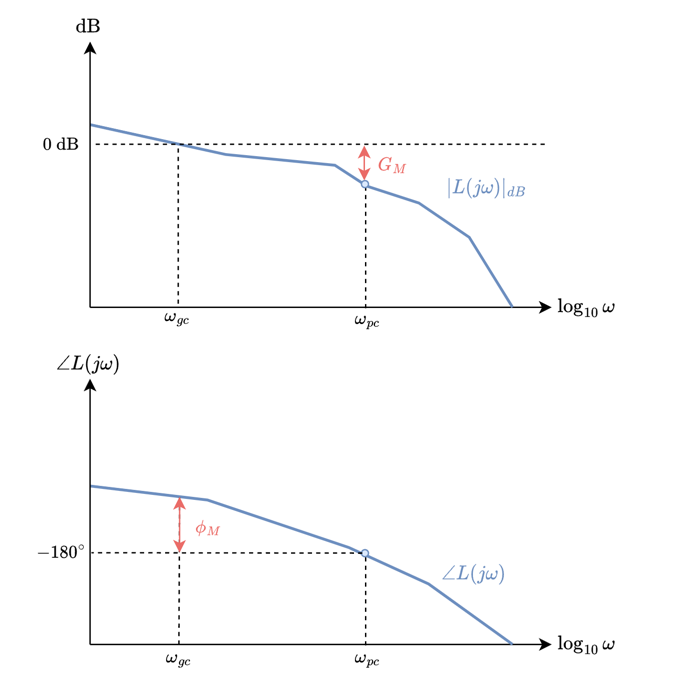

Note that in either case we are assessing how much gain or phase is required to make the frequency response have a value of $L(j\omega)=-1$, which corresponds with intercepting the critical point. The `margin `function is useful in this regard, as it plots the Bode diagram and then also overlays the gain and phase margins, as well as the corresponding phase crossover and gain crossover frequencies.

####   **Task: In the code block below, use the **`margin `**function to determine the gain margin and phase margin of **$L(s)=\frac{10(1+s)}{s^2(1+s/10)^2}$.

%Code block for task


####  Question 10: Using the resulting Bode diagram, what is the gain margin of the system?

When using a log-polar plot, the gain margin corresponds with the amount of gain required to raise the curve such that it passes through the critical point, which occurs at the phase crossover frequency $\omega_{pc}$. The phase margin (in degrees) corresponds to the amount of phase required to shift the curve leftwards such that it passes through the critical point, which occurs at the gain crossover frequency $\omega_{gc}}$. This is illustrated below.

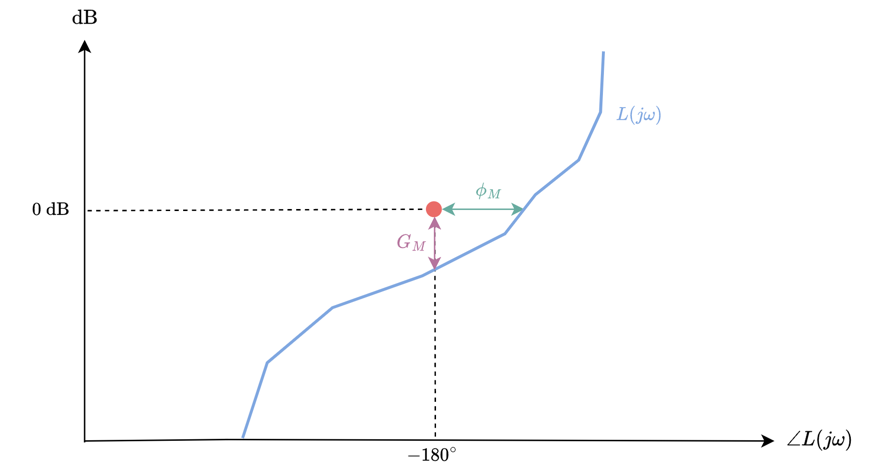

The log-polar plot of $L(s)=\frac{1}{s(1+s)^2}$ is generated using the code below, which provides the same information about gain and phase margin, albeit framed differently.

%Example
s = tf('s');
L = 1/s/(1+s)^2;

figure, hold on
nichols(L)

We can then read off the resulting log-polar plot to determine a gain margin of $G_M=6.02$ dB.

A gain margin of $6.02$ dB corresponds to an arithmetic gain of $10^{6.02/20}\approx 2$. We should therefore expect that our closed-loop system will be destabilised if we add a gain of $2$ or more to $L(s)$. This is demonstrated using the code block below, where for values of $k\geq 2$, 


$$T_k(s)=\frac{kL(s)}{1+kL(s)}$$
 

will become unstable, as shown with the resulting step responses. 

%Example
s = tf('s');
L = 1/s/(1+s)^2;

k = 1;

T = feedback(L,1);
Tk = feedback(k*L,1);

figure, hold on
nichols(L)
nichols(k*L)

figure, hold on
step(T,50)
step(Tk,50)
legend('y(t)','y_k(t)')

### Stability margin

The gain and phase margins are useful metrics to determine the loop transfer function's distance away from the critical point, and hence its level of stability. This is especially important when dealing with plant uncertainty (which is touched on in a later chapter). Specifically, we are working with an approximate model of our open-loop system, but the actual system that we are trying to control in feedback may have a different gain and phase profile, or have parameters that vary with time — hence the need for a gain and phase margin to give us some headroom in case our model is off. 

A drawback of gain and phase margin is that each quantity is treated independently of the other. In other words, gain margin considers gain variations when the phase remains unchanged at $-180^\circ$, and the phase margin considers phase variations without changing the unitary gain. Real-world systems are vulnerable to simultaneous gain and phase variations, which may not be adequately captured by the traditional gain and phase margin specifications. A fairly extreme example is shown below.

#### Example

Consider the loop transfer function, $L(s)=0.38\frac{s^2+0.1s+0.55}{s(s+1)(s^2+0.06s+0.5)}$. The log-polar plot of $L(s)$ is generated using the code below.

%Example
s = tf('s');
L = 0.38*(s^2+0.1*s+0.55)/s/(s+1)/(s^2+.06*s+0.5);

figure,clf
nichols(L)

[gm,pm] = margin(L)

The above system has an infinite gain margin and $~70^\circ$ phase margin, which gives us an impression that $L(j\omega)$ is far away from the critical point and quite safe from becoming unstable. However, visualisation on the log-polar plane shows that the frequency response locus actually comes very close to the critical point.

A more robust way of quantifying stability is to determine how close the frequency response comes to the critical point across all frequencies. Formally, we are trying to determine the Euclidean distance between the critical point of $-1$ and $L(j\omega)$, which can be written as

$|L(j\omega)-(-1)|=|L(j\omega)+1|$,

and then find the smallest $|L(j\omega)+1|$ across all frequencies ($\forall \omega\geq0$). In order to determine the smallest distance between the critical point and $L(j\omega)$, we can draw a circle on the Nyquist plot, centred at the critical point, and when the circle first intersects the $L(j\omega)$ locus, the corresponding radius is equal to the smallest distance, as shown below.

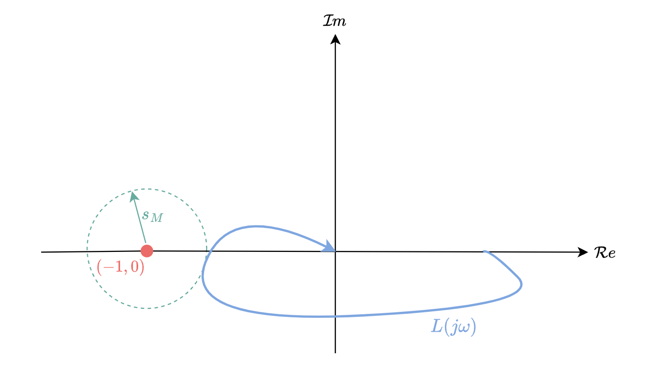

We refer to this radius as our **stability margin**, $s_M$, which considers both gain and phase variations in the open-loop system. This value is easy to read off a Nyquist plot, but is not always intuitive on a Bode diagram or log-polar plot, based on the logarithmic scale. That being said, in **Chapter 11** we will relate the stability margin with performance specifications on a log-polar plot, which will form the basis of our control design technique in this course. Reasonable stability margins are in often in the range of $0.5-0.8$.

####  Question 11: What is the relationship between the magnitude response at the phase crossover frequency, $|L(j\omega_{pc})|$, and the gain margin, $G_M$ (in arithmetic units)?

####  Question 12: Assuming the phase crossover frequency, $\omega_{pc}$, results in the smallest distance between $L(j\omega)$ and the critical point, determine the relationship between the safety margin, $s_M$, and gain margin, $G_M$ (in arithmetic units).

####  Question 13: Submit your completed Virtual Lab 6 live script. **The file name must be appended with your student number, e.g. VirtualLab6_SMTJOH999.slx.**  

***This concludes Virtual Lab 6.***